# Algoritmos Numéricos por Computadora

# Primer parcial - Primavera 2020

Cambia el nombre del script a NombreClaveúnica (ej: Marcelo123456).

Sube tu archivo resultado a comunidad $\to$ primerParcial antes de las 10am.

Calif: 

1 1 1 1 

1 1 1 1 

2 1 0.5 

0.5 1.33 1 1 1 

2.00 1 1 1 0 1.5 1 1 0.9 0.95 8.78

## Formato IEEE 754. Punto flotante de doble precisión.

1. [2 puntos] 

a) Explica a detalle la representación hexadecimal del número 2.125  en el  formato IEEE 754: $x=\textrm{signo}\;\left(1+f\right)2^e$. En el siguiente código inserta tus observaciones y cálculos para determinar: *signo*, *e*, *f *y *x*. 

% Escribe aquí tus observaciones y cálculos
xri = num2hex(2.125)

xri = '4001000000000000'

%El numero en hexa es 4001000000000000
% En este caso 4 -> 0100 y el bit mas significativo= 0.
%Si el primer bit es 0 => el numero es positivo (1)
%Si el primer bit es 1 => el numero es negativo (-1)
signo=1;

%Los primeros 3 caracteres sin contar el bit del signo 
beV= [4 0 0];
aux = [2 1 0];
be=sum(beV.*16.^aux); 
e= be-1023;

fVec = [1 0 0 0 0 0 0 0 0 0 0 0 0]; 
i = 1:13; 
f = sum(fVec./(16.^i)); %aqui convierto a decimal 1*16^-1+ 0*16^-2 ...
x1 = signo*(1 + f) * 2^e;
disp(x1); %aqui se ve que el resultado nos da 2.1250 

    2.1250



b) Repite ejercicio anterior pero ahora con el número -1.1

x2 = num2hex(-1.1)

x2 = 'bff199999999999a'

%El numero en hexa es bff199999999999a
% En este caso b -> 1011 y el bit mas significativo= 0.
%Si el primer bit es 0 => el numero es positivo (1)
%Si el primer bit es 1 => el numero es negativo (-1)
signo=-1;

%Los primeros 3 caracteres sin contar el bit del signo ((b=11)-8)=3 => 3ff
beV= [3 15 15];
aux = [2 1 0];
be=sum(beV.*16.^aux);
e= be-1023;

fVec = [1 9 9 9 9 9 9 9 9 9 9 9 10]; 
i = 1:13;
f = sum(fVec./(16.^i)); %aqui convierto a decimal 1*16^-1+ 9*16^-2 ...
x2 = signo*(1 + f) * 2^e;
disp(x2); %aqui se ve que el resultado nos da -1.100.

   -1.1000



## Raíces de funciones

2. [2 puntos] Considera un tanque esférico de radio R. El volumen del líquido contenido en el tanque es función de la altura h:


$$V=\pi h^2 \left(\frac{3R-h}{3}\right)$$


Calcula a qué altura hay que llenar un tanque de radio R=3 *m* para tener un volumen V= 30 $m^3$. 

Utiliza el método de la secante (escribe el código más abajo) o utiliza la función fzero de Matlab.

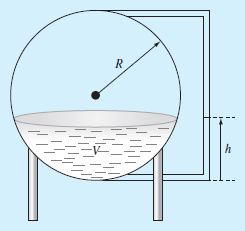

% El código no debe generar warnings (no genera warnings yei)
r=3;
vol= @(h) ((pi*h.^2).*(3*r-h)/3)-30 

vol = function_handle with value:
    @(h)((pi*h.^2).*(3*r-h)/3)-30


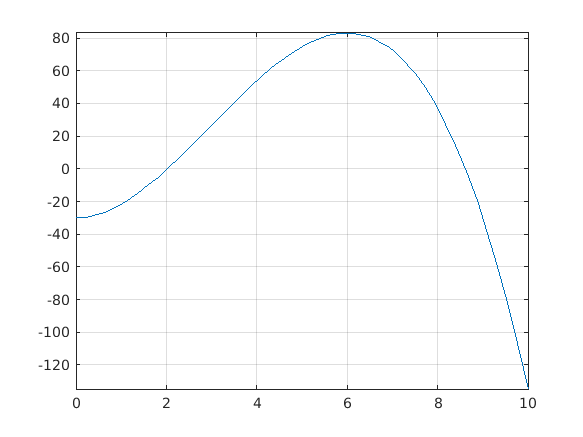

fplot(vol, [0,10])
grid on

%tenemos 2 raices positivas por que h es cubica (la tercer raiz es
%negativa)
[h1,ih1]=secante(vol,0,4)

h1 = 2.0269

ih1 = 9

[h2,ih2]=secante(vol,6,10)

h2 = 8.6139

ih2 = 11

3. [2 puntos] Determina todas las raíces de $f\left(x\right)=-14-20x+19x^2 -3x^3$. Grafica el polinomio para identificar en qué regiones se encuentran las raíces.

% El código no debe generar warnings (tampoco genera warnings yei)
f= @(x) -14 -20*x +19*x.^2-3*x.^3

f = function_handle with value:
    @(x)-14-20*x+19*x.^2-3*x.^3


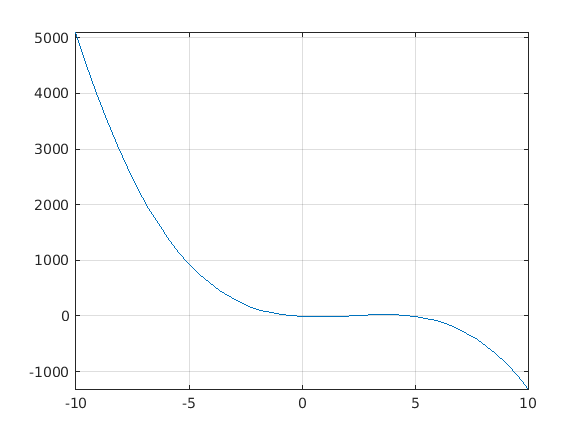

fplot(f,[-10,10]) %hay 3 raices en la funcion, me fui moviendo jugando con los valores.
grid on

[r1,i1]=newtonRaphson(f,-.5)

r1 = -0.4723

i1 = 5

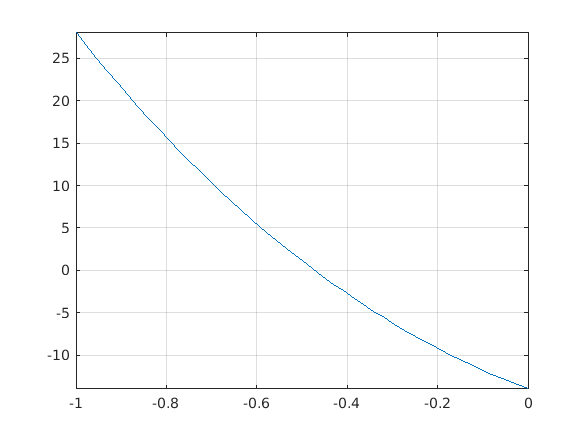

fplot(f,[-1,0]) %hay 3 raices en la funcion, me fui moviendo jugando con los valores.
grid on

[r2,i2]=newtonRaphson(f,2.5)

r2 = 2.0997

i2 = 5

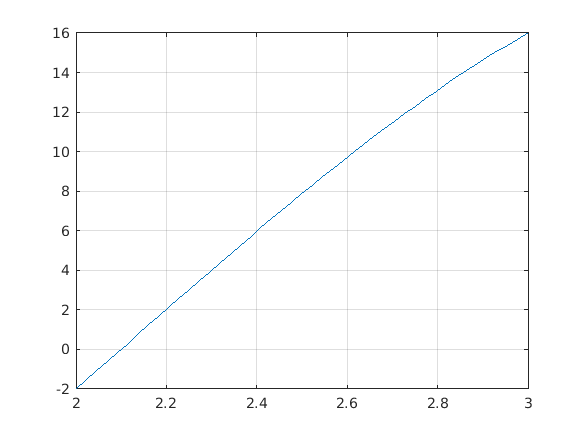

fplot(f,[2,3]) %hay 3 raices en la funcion, me fui moviendo jugando con los valores.
grid on

[r3,i3]=newtonRaphson(f,4.5)

r3 = 4.7060

i3 = 5

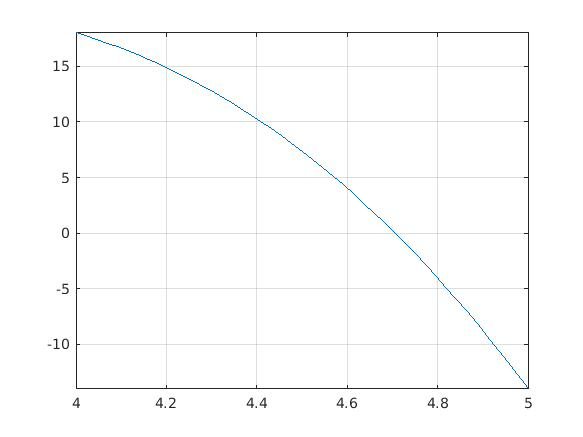

fplot(f,[4,5]) %hay 3 raices en la funcion, me fui moviendo jugando con los valores.
grid on

## Optimización

4. [2 puntos] Encuentra el máximo de la función


$$f\left(x\right)=2\sin \left(x\right)-\frac{x^2 }{10}$$


en el intervalo [0,5].

Utiliza el método de Newton (escribe el código más abajo) o utiliza la función fminbnd de Matlab.

fOp= @(x) 2*sin(x)-(x.^2)/10

fOp = function_handle with value:
    @(x)2*sin(x)-(x.^2)/10


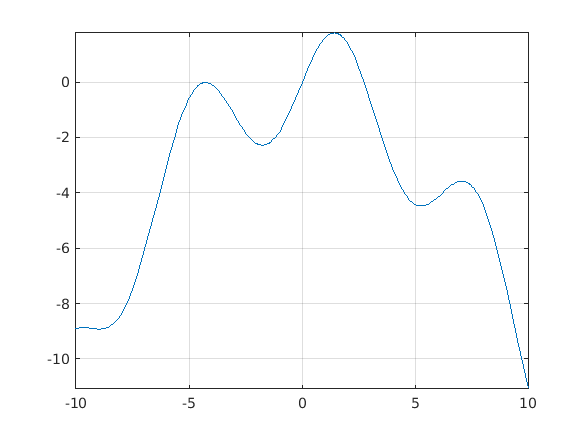

fplot(fOp, [-10,10])
grid on

[max,i, min]=NewtonOptimizacion(fOp,1) %este es el max

max = 1.4276

i = 5

min = logical
   0


fmax=fOp(max)

fmax = 1.7757

[minL,i,min]=NewtonOptimizacion(fOp,4) %min local para probar el metodo

minL = 5.2671

i = 7

min = logical
   1


5. [1 punto] Método de la secante.

function [x,i] = secante(f, a, b)
    MAX=100;
    rtol=eps;
    i=0;
    
    do=true;
    
    while do
        fx1=f(a);
        fx2=f(b);
        
        sn=(fx1-fx2)/(a-b);
        b=a;
        a=a-(fx1/sn);

        i=i+1;
        do= i<MAX && abs(a-b)>abs(a)*rtol && fx1~=0;
    end
    x=a;
end

6. [1 punto] Método de Newton para encontrar puntos críticos. 

Observa que la función debe regresar tres resultados. La variable min indíca si el punto crítico es un mínimo o un máximo.

function [x,i,min] = NewtonOptimizacion(f,x)
    fsym= sym(f);
    dfs=diff(fsym);
    df = matlabFunction(dfs);
    
    [x,i]= newtonRaphson(df,x);
    
    %Para checar si es mas o min vemos si es creciente o decreciente antes
    %del optimo.
    if f(x)<f(x-1)
        min=true;
    else
        min=false;
    end
end


#### Newton Raphson para encontrar raices

function [x,i] = newtonRaphson(f,x)
    %derivo dos veces la funcion 
    fsym= sym(f);
    dfs= diff(fsym);
    df= matlabFunction(dfs);
    
    if nargin(df) == 0
        cte=df();
        df= @(x) cte + 0*x;
    end
    
    MAX=100;
    rtol=eps;
    
    %x=(a+b)/2;
    i=0;
    
    do=true;
    while do
        xp=x;
        x=xp-f(xp)/df(xp);
        fx=f(x);
        i=i+1;
        do=(abs(x-xp)/abs(x)>rtol && fx~=0 && i<MAX);
    end
end